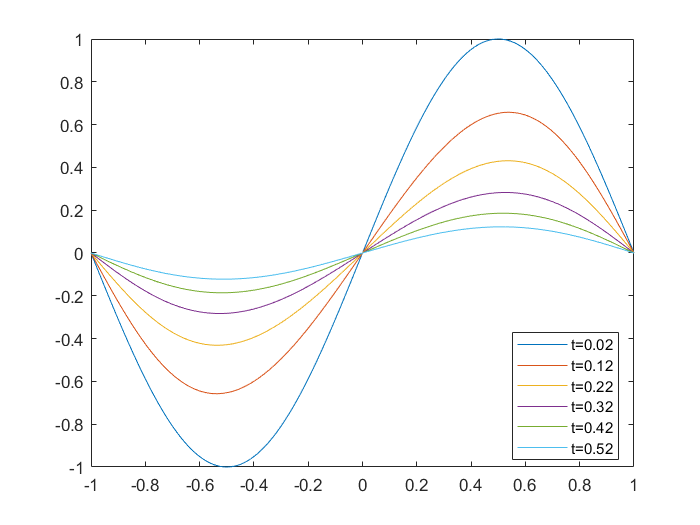

clear
m = 0;
options = odeset('Events',@pdevents);
Nx = 300;
x = linspace(-1,1,Nx);
Nt = 60;
t = linspace(0,0.5,Nt);
[sol,tsol,sole,te,ie] = pdepe(m,@oscpde,@oscic,@oscbc,x,t,options);

figure
ii = 1:10:60;
for i = ii
    plot(x, sol(i,:))
    hold on
end
tt = ii/50;
legend('t=0.02','t=0.12', 't=0.22', 't=0.32', 't=0.42', 't=0.52', 'Location', 'best')

N = 20;
rand_x = (1:16:length(x));
rand_t = (1:3:length(t))';
rand_x = [rand_x, length(x)-1]';
t_u_train = zeros(N*N,1); x_u_train=t_u_train; u_train=x_u_train;
ii = 1;
for i = 1:1:length(rand_x)
    for j = 1:1:length(rand_t)
        
        t_u_train(ii) = t(rand_t(j));
        x_u_train(ii) = x(rand_x(i));
        u_train(ii) = sol(rand_t(j), rand_x(i));
        ii = ii + 1;
        
    end
end
Nf = 100;
f_train = 0.1*rand(Nf,1) - 0.05;
t_f_train = t_u_train(1:3:Nt);
t_f_train = [t_f_train; t_f_train; t_f_train; t_f_train; t_f_train];
x_f_train = x_u_train(1:3:Nx);

x_test = [];
for i = 1:1:Nt
    x_test = [x_test, x'];
end
x_test = x_test';
t_test = [];
for i = 1:1:Nx
    t_test = [t_test, t'];
end
u_test = sol;
save('Burgy.mat','x_u_train','t_u_train','u_train','x_f_train','t_f_train','f_train', 'x_test', 't_test', 'u_test');

### Check viscosità

xt = [];

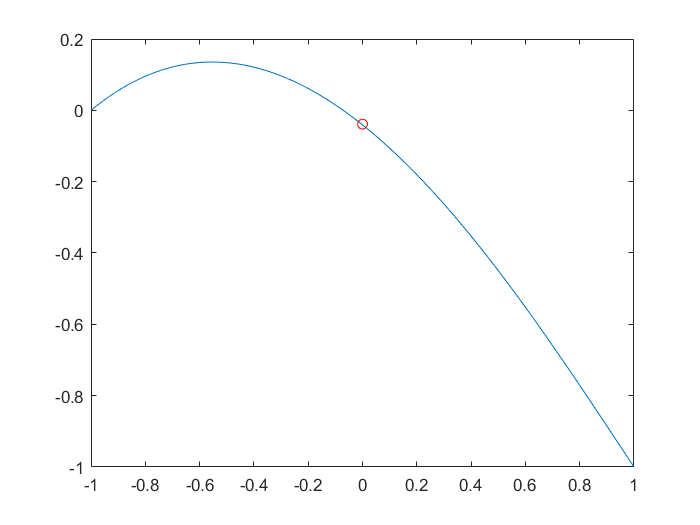

m = 0;
options = odeset('Events',@pdevents);
Nx = 300;
x = linspace(-1,1,Nx);
Nt = 60;
t = linspace(0.1,0.5,Nt);
[sol,tsol,sole,te,ie] = pdepe(m,@oscpde,@oscic,@oscbc,x,t,options);

xx = sol(end, 150);
xt = [xt; xx];
figure
plot(x, sol(end,:))
hold on
plot(0,xx,'ro')

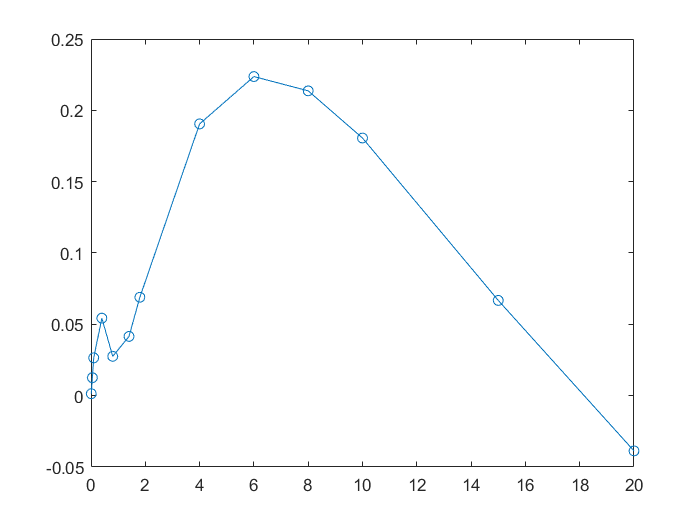

figure
plot([0.01, 0.05, 0.1, 0.4, 0.8 , 1.4, 1.8, 4, 6, 8, 10, 15., 20], xt, '-o')